# **Practice 3 - Non-Linear Optimization with Constraints**

**Andrés Herencia y Antonio Fernández**

**MUTECI 2023-2024**

## **Exercise 1**

For the following nonlinear problem

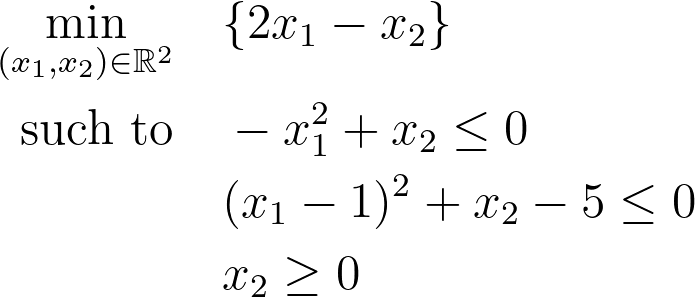

It is requested

a. Determine the KKT points. 

b. Identify the optimum from the previous points. 

c. Use MATLAB (or any other software) to identify the optimum starting from various points, for example, (-0.5, -0.5); (0.5, 0.5); (2, 1) and verify if the same solution is reached. 

d. Perform two iterations with the Zoutendijk algorithm starting from the point (2, 1).

### Solution

Before starting to compute, we can represent the function to make some interpretations about the solution.

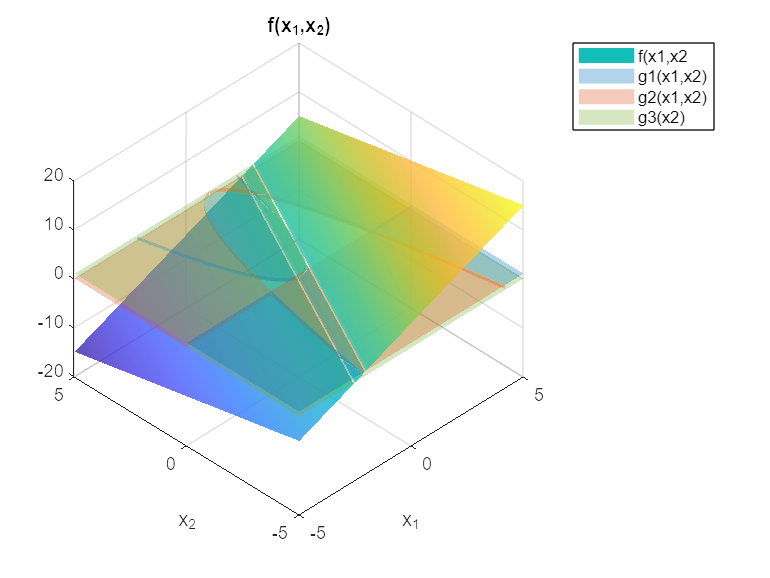

clear; clc; clf;

f = @(x1,x2) 2.*x1 - x2;
g1 = @(x1,x2) -x1.^2 + x2 <=0;
g2 = @(x1,x2) x1.^2 - 2.*x1 + 1 + x2 - 5 <=0;
g3 = @(x1,x2) -x2 <= 0;

[Xgrid,Ygrid]=meshgrid(-5:0.01:5,-5:0.01:5);
z = f(Xgrid,Ygrid); z1 = g1(Xgrid,Ygrid); z2 = g2(Xgrid,Ygrid); z3 = g3(Xgrid,Ygrid);

fig1 = figure(1);
surface(Xgrid,Ygrid,z,'EdgeColor','none','FaceAlpha',0.8)
hold on
s1 = surface(Xgrid,Ygrid,z1,'FaceColor','[0 0.4470 0.7410]', ...
    'FaceAlpha',0.3, 'EdgeColor','none');
s2 = surface(Xgrid,Ygrid,z2,'FaceColor','[0.8500 0.3250 0.0980]', ...
    'FaceAlpha',0.3, 'EdgeColor','none');
s3 = surface(Xgrid,Ygrid,z3,'FaceColor','[0.4660 0.6740 0.1880]', ...
    'FaceAlpha',0.3, 'EdgeColor','none');
hold off
grid on
title('f(x_1,x_2)')
xlabel('x_1')
ylabel('x_2')
view([-45 -45])
legend('f(x1,x2','g1(x1,x2)','g2(x1,x2)','g3(x2)')

view([-45 45])

#### a) Determine the KKT points. 

We will compute te KKT points.

syms x1 x2 u1 u2 u3;

obj = 2.*x1 -x2;
ineq1 = -x1.^2 + x2;
ineq2 = (x1 - 1).^2 + x2 - 5;
ineq3 = -x2;

L = obj + u1*ineq1 +u2*ineq2 +u3*ineq3;
dL_dx1 = diff(L, x1);
dL_dx2 = diff(L, x2);

eq1 = dL_dx1 == 0;
eq2 = dL_dx2 == 0;
eq3 = u1*ineq1 == 0;
eq4 = u2*ineq2 == 0;
eq5 = u3*ineq3 == 0;

sol = solve([eq1, eq2, eq3, eq4, eq5], [x1, x2, u1, u2, u3]);

KKTpoints = [];

for i = 1:length(sol.x1)

    x1_sol = sol.x1(i);
    x2_sol = sol.x2(i);
    u1_sol = sol.u1(i);
    u2_sol = sol.u2(i);
    u3_sol = sol.u3(i);

    if subs(ineq1, [x1, x2], [x1_sol,x2_sol])<=0 && ...
        subs(ineq2, [x1, x2], [x1_sol,x2_sol])<=0 && ...
        subs(ineq3, [x1, x2], [x1_sol,x2_sol])<=0
        if u1_sol >= 0 && u2_sol >= 0 && u3_sol >= 0
            KKTpoints = [KKTpoints; [x1_sol, x2_sol]];
        end
    end
end

disp(KKTpoints)

$$\left(\begin{array}{cc} 1 & 1\\ -1 & 1\\ 2 & 4 \end{array}\right)$$

#### b) Identify the optimum from the previous points. 

We evaluate the function at each point and check when it achieves the lowest value.

subs(obj, [x1, x2], [KKTpoints(1,1),KKTpoints(1,2)])

$$ans = 1$$

subs(obj, [x1, x2], [KKTpoints(2,1),KKTpoints(2,2)]) % minimum value

$$ans = -3$$

subs(obj, [x1, x2], [KKTpoints(3,1),KKTpoints(3,2)])

$$ans = 0$$

**The optimum from the previous points is **$\left(-1,1\right)\;$** with value **$-3\ldotp$

We can represent the points in a figure

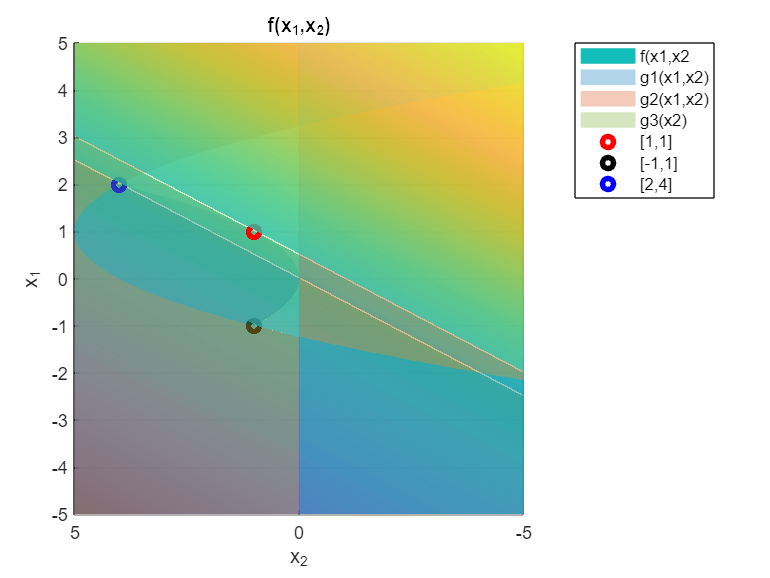

fig1;
hold on
plot3(1, 1, f(1,1),'ro','LineWidth',3);
plot3(-1, 1, f(-1,1),'ko','LineWidth',3);
plot3(2, 4, f(2,4),'bo','LineWidth',3);

view([-40.8 6.0])
legend('f(x1,x2','g1(x1,x2)','g2(x1,x2)','g3(x2)','[1,1]','[-1,1]','[2,4]')
view([-90 90])

#### c) Use MATLAB (or any other software) to identify the optimum starting from various points, for example, `(-0.5, -0.5)`;` (0.5, 0.5)`; `(2, 1)` and verify if the same solution is reached. 

x0 = [-0.5 ; -0.5];
lb = [-inf, 0]

lb =   -Inf     0


[x,fun,exitflag, output]=fmincon(@top_ejem_pnl_obj,x0,[],[],[],[],lb,[],@top_ejem_pnl_res);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x % optimum achieved

x =    -1.0000
    1.0000


x0 = [0.5 ; 0.5];
[x,fun,exitflag, output]=fmincon(@top_ejem_pnl_obj,x0,[],[],[],[],lb,[],@top_ejem_pnl_res);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x % nearly [0,0], not a feasible point

x = 1.0e-03 *

    0.6002
    0.0002


This is almost [0,0].

x0 = [2 ; 1];
[x,fun,exitflag, output]=fmincon(@top_ejem_pnl_obj,x0,[],[],[],[],lb,[],@top_ejem_pnl_res);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x % a kkt point

x =     2.0000
    4.0000


Depending on the starting point, we get different solutions. This is due to the set of constraints of **our** **problem is not convex**, which means that the function can have more than one minimum, so we can not guarantee that we will achieve the global minimum when a local minimum is found. In these types of problems, the algorithm is extremely sensitive to the initial point. Additionally, as the convergence of the problem is difficult, we generally require specific algorithms for its resolution. For these type of problems, we could use the [Global Optimization Toolbox](https://www.mathworks.com/products/global-optimization.html) or another external solver such as [Knitro](https://www.artelys.com/solvers/knitro/), but it is not the aim of this practice.

NOTE: all the `top_ejem_pnl` functions can be found on annexes.

#### d) Perform two iterations with the Zoutendijk algorithm starting from the point [`2, 1]`.

All the own-made function can be found in annexes.

**First iteration**

x0 = [2, 1]

x0 =      2     1


%Active restrictions
restrictions = {ineq1, ineq2, ineq3};

for i = 1:numel(restrictions)
    result = round(subs(restrictions{i}, [x1, x2], x0),4);
    if result == 0
        disp(['The constraint ', num2str(i), ' is equal to zero.']);
    else
        disp(['The constraint ', num2str(i), ' is not equal to zero.']);
    end
end

The constraint 1 is not equal to zero.
The constraint 2 is not equal to zero.
The constraint 3 is not equal to zero.


grad = gradient(obj, [x1, x2])

$$grad = \left(\begin{array}{c} 2\\ -1 \end{array}\right)$$

A = [-1,2,-1; 0,1,0; 0,0,1; 0,-1,0; 0,0,-1];
c = [1;0;0];
b = [0;1;1;1;1];

lb(1:3)=-Inf;

x=linprog(c,A,b,[],[],lb);

Optimal solution found.



display(x)

x =     -3
    -1
     1


As $z=-3<0\;$then $\left(-1,1\right)$ is a descent direction.

xp = 0;
lb = 0;
[l,fun,flag]=fmincon(@top_ejem_pnl_obj2,xp,[],[],[],[],lb,[],@top_ejem_pnl_res2);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


display(l)

l = 0.6972

xk1=x0+l*[x(2),x(3)]

xk1 =     1.3028    1.6972


The first iteration give us $x_1 =\left(1\ldotp 3028,1\ldotp 6972\right)$.

**Second iteration**

for i = 1:numel(restrictions)
    result = round(subs(restrictions{i}, [x1, x2], xk1),4);
    if result == 0
        disp(['The constraint ', num2str(i), ' is equal to zero.']);
    else
        disp(['The constraint ', num2str(i), ' is not equal to zero.']);
    end
end

The constraint 1 is equal to zero.


The constraint 2 is not equal to zero.
The constraint 3 is not equal to zero.


gradienterest = gradient(ineq1, [x1, x2]);
A = [-1,2,-1;-1,-2*xk1(1),1;0,1,0;0,0,1;0,-1,0;0,0,-1];
c = [1;0;0];
b = [0;0;1;1;1;1];

lb(1:3)=-Inf;

x=linprog(c,A,b,[],[],lb);

Optimal solution found.



display(x)

x =    -0.1315
    0.4343
    1.0000


As $z=-0\ldotp 1315<0\;$then $\left(0\ldotp 4343,1\right)$ is a descent direction.

xp = 0;
lb = 0;
[l,fun,flag]=fmincon(@top_ejem_pnl_obj3,xp,[],[],[],[],lb,[],@top_ejem_pnl_res3);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


display(l)

l = 1.9655

xk2=xk1+l*[x(2),x(3)]

xk2 =     2.1563    3.6627


Since the local minimum in that region is located at $\left(2,4\right)$, it seems that $\left(2\ldotp 1563,3\ldotp 6627\right)$ is a good result.

## Exercise 2

For the following linear programming problem:

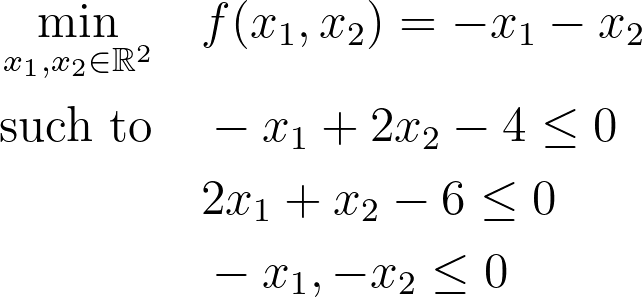

Perform two iterations with the primal-dual interior-point algorithm, either by hand or by programming, whichever is more convenient.

### Solution

The `primaldual` function is given in the annexes.

A = [-1,2;2,1];
b = [4;6];
c = [-1;-1];
eps = 0.001;
rho = 0.09;
sigma = 0.1;

sol = primal_dual_interior_point(A, b, c, eps, rho, sigma, 4);
display(sol);

sol =     1.6458    2.8458


## Annexes

### Exercise 1. c)

#### Objective function

function f= top_ejem_pnl_obj(x)
%% Objective function of the exercise 1, practice 3
    f = 2.*x(1) - x(2);
end

#### Constraints

 function [c , ceq]= top_ejem_pnl_res(x)
 %% Constraints associated to the objective function of the exercise 1, practice 3
    ceq=[ ];
    c=[-x(1).^2+x(2); (x(1)-1).^2+x(2)-5; -x(2)];
 end

### Exercise 1. d)

#### First iteration

**Objective function**

function f= top_ejem_pnl_obj2(l)
%% Objective function for the first iteration of the Zoutendijk algorithm
    f = -3*l;
end

**Constraints**

function [c , ceq]= top_ejem_pnl_res2(l)
%% Constraints associated to the objective function in the first iteration
% of the Zoutendijk algorithm
    ceq=[ ];
    c=[-(2-l)^2+1+l;(1-l)^2+l-4;-l-1];
end

#### Second iteration

**Objective function**

function f= top_ejem_pnl_obj3(l)
%% Objective function for the second iteration of the Zoutendijk algorithm
    x=[1.3028, 1.6972];
    d=[0.4343, 1];
    sust=x + l*d;
    f = 2*sust(1) -sust(2); 
end

**Constraints**

function [c , ceq]= top_ejem_pnl_res3(l)
%% Constraints associated to the objective function in the second iteration 
% of the Zoutendijk algorithm
    x=[1.3028,1.6972];
    d=[0.4343,1];
    sust=x+l*d;
    ceq=[];
    c=[-sust(1).^2 + sust(2);(sust(1) - 1).^2 + sust(2) - 5;-sust(2)];
end

### Exercise 2

#### Primal-dual function

function [sol,flag, prompt] = primal_dual_interior_point(A, b, c, eps, rho, sigma, niter)
%% primal_dual_interior_point: Solves linear programming problems using the primal-dual interior-point algorithm.
%
%   [sol, flag, prompt] = PRIMAL_DUAL_INTERIOR_POINT(A, b, c, eps, rho, sigma, niter) solves the linear programming problem
%
%      minimize  c' * x
%      subject to  A * x = b
%                  x >= 0
%
%   using the primal-dual interior-point algorithm. It returns the optimal solution 'sol', a flag 'flag', and a status message 'prompt'.
%
%   Input:
%      A      - Coefficient matrix for equality constraints (m x n)
%      b      - Right-hand side of equality constraints (m x 1)
%      c      - Coefficient vector for the objective function (n x 1)
%      eps    - Tolerance for stopping criterion
%      rho    - Step size parameter
%      sigma  - Barrier parameter
%      niter  - Maximum number of iterations
%
%   Output:
%      sol    - Optimal solution to the linear program (n x 1)
%      flag   - Flag indicating the result:
%               -2: Infeasible solution
%               -1: Unbounded solution
%                1: Optimal solution found
%      prompt - Status message describing the result

% Initialization
x0=A.'*inv(A*A.')*b;
u0=inv(A*A.')*A*c;
s0=c-A.'*u0;

% Minimum
minx=min(x0);
mins=min(s0);
delx=max(-(3/2)*minx,0);
dels=max(-(3/2)*mins,0);

x0=x0+delx;
s0=s0+dels;

delxx=(1/2)*(x0.'*s0)/(ones(size(x0)).'*s0);
delss=(1/2)*(x0.'*s0)/(ones(size(s0)).'*x0);

x0=x0+delxx;
s0=s0+delss;

% Initial solution, first step
x=x0;
u=u0;
s=s0;

% Iterations
step=Inf;
iter=0;
while (step > eps) | (iter < niter)

    % Initial conditions of each step.
    iter = iter+1;
    n = length(x);
    m = length(u);
    X = diag(x);
    S = diag(s);
    mu = sigma*(s.'*x)/n;

    % dw = A*Z; with A = inv(M).
    bb1=mu*ones(n,1)-X*S*ones(n,1);
    bb2=b-A*x;
    bb3=c-A.'*u-s;

    M=[S, zeros(n,m), X; A, zeros(m,m), zeros(m,n); zeros(n,n), A.', eye(n)];

    Z=[bb1;bb2;bb3];

    dw = inv(M)*Z;

    % Subvectors which will evaluate each step of the algorithm.
    % dw = [dx, du, ds]
    dx=zeros(1,n);
    for i=1:n
        dx(i)=dw(i);
    end
    dx=dx.';

    du=zeros(1,n+m);
    for i=(n+1):(n+m)
        du(i)=dw(i);
    end
    du(1:n)=[]; du=du.';

    ds=zeros(1,n+m+n);
    for i=(n+m+1):(n+m+n)
        ds(i)=dw(i);
    end
    ds(1:(n+m))=[]; ds=ds.';

    % Evaluation
    if all(ds>=0)
        prompt = 'Feasible solution does not exists. Initial point returned.';
        flag = -2;
        sol = x0;
        break
    elseif all(dx >= 0)
        prompt = 'Not bounded solution. -Inf returned.';
        flag = -1;
        sol = -Inf;
        break
    else

        % Computing alpha_p and alpha_d 
        alpha_p_vector=-x(dx < 0)./dx(dx < 0);
        alpha_d_vector=-s(ds < 0)./ds(ds < 0);

        alpha_p=rho * min(alpha_p_vector); % Primal step magnitude.
        alpha_d=rho * min(alpha_d_vector); % Dual step magnitude.

        % New slack variable for the dual problem
        s = s + alpha_d.*ds;
        % New solution for the dual problem
        u = u + alpha_d.*du;
        % New solution for the primal problem
        x = x + alpha_p.*dx;
        % step
        step = (c.'*x-b.'*u);
        prompt = sprintf('Iteration %d; Duality step: %.4f.', iter, step);
        flag = 1;
        sol = x.';
    end
end
end